## The transfer matrix of the four tank system is considered as:

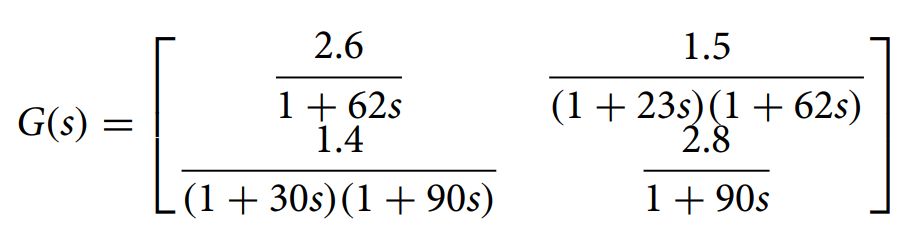

clear
s = tf('s');
G11 = 2.6/(1+62*s);
G12 = 1.5/(1+23*s)/(1+62*s);
G21 = 1.4/(1+30*s)/(1+90*s);
G22 = 2.8/(1+90*s);
G = [G11 G12; G21 G22];

MIMO_sys = MIMOSystem(G)

MIMO_sys =   MIMOSystem with properties:

             G: [2×2 tf]
        numOut: 2
         numIn: 2
           Kdc: [2×2 double]
           RGA: []
            Kc: []
       pairing: []
    sampleTime: []
            SR: []
      mpcParam: []


MIMO_sys.desiredSamplTime();

Recommended sample time: 2.3000 units


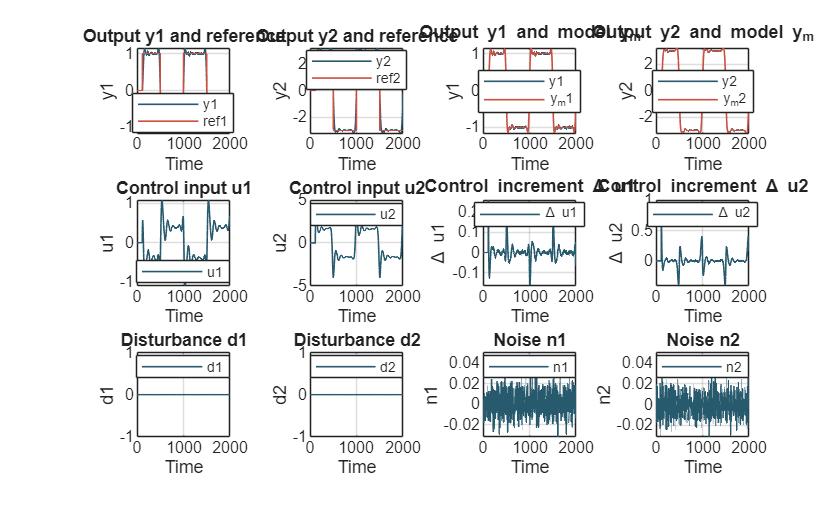

mpcParams.model = 'DMC';
mpcParams.modelHorizon = 50; % model horizon (step response length) [N]
mpcParams.predictionHorizon = 50; % prediction horizon [P]
mpcParams.controlHorizon = 30; % control horizon [M]
mpcParams.method = 'programmed'; % 'programmed' or 'unprogrammed'
mpcParams.alpha = 0.01; % filter parameter for setpoint (yref)
mpcParams.Q = 1; % output weighting matrix
mpcParams.R = 1; % input weighting matrix
% ___________________________________________________________________
% Define reference signals
% You can Also define your desired reference signal vector and replace it with
% "Ref" variable below!
type = 'square'; % Type of wave ('sine' or 'square')
T = 1000; % Period
% Here below you can choose amplitude and time-shift of your reference
% signal channels individually.
% time-shift allows you to have square or sine wave signals with different
% rising/falling times in channels.

shiftscale = [0, 0]; % Shift scales (must be from 0 to 1)
refAmplitude = [1, 3]; % Amplitudes
% ___________________________________________________________________
ts = MIMO_sys.sampleTime; % sample time (sec)
T0 = 0; % simulation start (sec)
Tf = 2000; % simulation end (sec)
t = T0:ts:Tf;
t = t'; % time vector
% ___________________________________________________________________
% Setpoint
yRef = referenceInput(MIMO_sys.numOut, t, mpcParams.predictionHorizon, type, T, shiftscale, refAmplitude, mpcParams.alpha);
% ___________________________________________________________________
% Disturbance
events = cell(1, MIMO_sys.numOut);
% Output 1: pulse from 300 to 500 with amplitude +0.5
events{1} = struct('type','pulse','t0',300,'tf',500,'amp',0.5);
% Output 2: pulse from 600 to 700 with amplitude -0.7
events{2} = struct('type','pulse','t0',600,'tf',700,'amp',-0.7);
disturbance = disturbanceInput(MIMO_sys.numOut, t, 'events', events, 'alpha', 0.01)*0;
% ___________________________________________________________________
% Noise (white noise with zero mean)
% You can add other types of noise if you want then replace with variable
% "noise"
StandardDev = 0.01; % noise standard deviation
noise = StandardDev * randn(numel(t), MIMO_sys.numOut);
% MIMO_sys.sampleTime = 0.5;
% ___________________________________________________________________
MIMO_sys.MPCdesign(mpcParams);
[index, Y, Ym, U, dU] = MIMO_sys.simMPC(t, yRef, noise, disturbance);
% GPC_plot(num_in, MIMO_sys.numOut, t, mpcParams.predictionHorizon, index, Y, Ym, yRef, U, dU, disturbance, noise)
MIMO_sys.MPCplot(t, index, Y, Ym, yRef, U, dU, disturbance, noise)